data = importfile("StormEvents_2014.csv")

data = 59465×23 table
    EpisodeID     Event_ID         State        Year     Month         Event_Type          Begin_Date_Time      Timezone       End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                                                                                                                                 

summary(data);

Variables:

    EpisodeID: 59465×1 double

        Values:

            Min            80464
            Median         85776
            Max       1.1032e+05

    Event_ID: 59465×1 double

        Values:

            Min        4.819e+05
            Median    5.1989e+05
            Max       7.4395e+05

    State: 59465×1 categorical

        Values:

            ALABAMA                    890  
            ALASKA                     172  
            AMERICAN SAMOA               1  
            ARIZONA                    570  
            ARKANSAS                  1259  
            ATLANTIC NORTH             553  
            ATLANTIC SOUTH             489  
            CALIFORNIA                1141  
            COLORADO                  1458  
            CONNECTICUT                170  
            DELAWARE                   161  
            DISTRICT OF COLUMBIA        36  
            E PACIFIC                    9  
        

groupcounts(data.Event_Type);

ans =           62
          42
         684
         106
        1146
          62
         794
           1
        3009
          11


%data.Begin_Date_Time(ismissing(data.Begin_Date_Time)) = 0;
%data.End_Date_Time(ismissing(data.End_Date_Time)) = 0;

data.lastingEvent = data.End_Date_Time - data.Begin_Date_Time;

longLastingEvent = groupsummary(data, "Event_Type","max","lastingEvent")

longLastingEvent = 48×3 table
          Event_Type           GroupCount    max_lastingEvent
    _______________________    __________    ________________

    Astronomical Low Tide           62           16:30:00    
    Avalanche                       42           48:00:00    
    Blizzard                       684           48:00:00    
    Coastal Flood                  106           96:00:00    
    Cold/Wind Chill               1146           90:00:00    
    Debris Flow                     62          155:00:00    
    Dense Fog                      794           36:00:00    
    Dense Smoke                      1           02:15:00    
    Drought                       3009          743:59:00    
    Dust Devil                      11           02:00:00    
    Dust Storm                     114           33:41:00    
    Excessive Heat                  83          175:00:00    

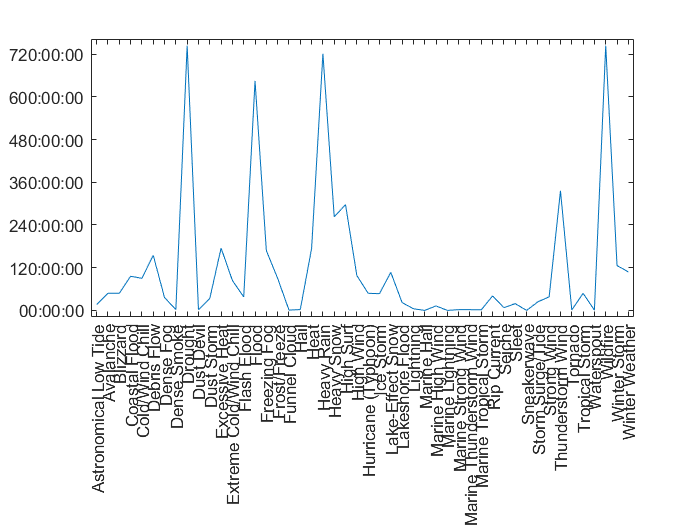

%histogram(longLastingEvent)
plot(longLastingEvent.Event_Type, longLastingEvent.max_lastingEvent);

data2 = data;
data2

data2 = 59465×24 table
    EpisodeID     Event_ID         State        Year     Month         Event_Type          Begin_Date_Time      Timezone       End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                                                                                                                                


data2.Event_Type = addcats(data2.Event_Type,{'<New Category>'});
data2.Event_Type = renamecats(data2.Event_Type,'<New Category>','FloodAll');
data2.Event_Type = mergecats(data2.Event_Type,{'FloodAll','Flash Flood','Flood'})

data2 = 59465×24 table
    EpisodeID     Event_ID         State        Year     Month         Event_Type          Begin_Date_Time      Timezone       End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                                                                                                                                


FloodTable = data2(data2.Event_Type == 'FloodAll',:);

FloodTable.Property_Cost(ismissing(FloodTable.Property_Cost)) = 0;
FloodTable.Crop_Cost(ismissing(FloodTable.Crop_Cost)) = 0;

FloodTable.Total_Cost = FloodTable.Property_Cost + FloodTable.Crop_Cost;

maxCost = groupsummary(FloodTable, 'State', 'max', 'Total_Cost')

maxCost = 54×3 table
           State            GroupCount    max_Total_Cost
    ____________________    __________    ______________

    ALABAMA                     91            2.7e+07   
    ALASKA                      31           3.11e+05   
    AMERICAN SAMOA               1                  0   
    ARIZONA                    156              5e+06   
    ARKANSAS                   102          4.525e+06   
    CALIFORNIA                 270          6.745e+06   
    COLORADO                   106              3e+05   
    CONNECTICUT                 16                  0   
    DELAWARE                    11                  0   
    DISTRICT OF COLUMBIA         5                  0   
    FLORIDA                    154            1.5e+08   
    GEORGIA                     46            2.5e+05   
    HAWAII                      13                  0   
    IDAHO            

%max(maxCost.max_Total_Cost)
maxCost = sortrows(maxCost,'max_Total_Cost','descend')

lightningEvents = data2(data2.Event_Type == 'Lightning',:);
lightningEventsSummer = lightningEvents(ismember(lightningEvents.Month,{'August','July','June'}),:)

lightningEventsSummer = 337×24 table
    EpisodeID     Event_ID         State        Year    Month    Event_Type      Begin_Date_Time      Timezone       End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                                                                                                                            

%groupsummary(lightningEventsSummer,'State','max','Event_Type')
summary(lightningEventsSummer);

Variables:

    EpisodeID: 337×1 double

        Values:

            Min            84489
            Median         87554
            Max       1.1032e+05

    Event_ID: 337×1 double

        Values:

            Min       5.1112e+05
            Median     5.316e+05
            Max       6.5905e+05

    State: 337×1 categorical

        Values:

            ALABAMA                     5   
            ALASKA                      0   
            AMERICAN SAMOA              0   
            ARIZONA                     6   
            ARKANSAS                    9   
            ATLANTIC NORTH              0   
            ATLANTIC SOUTH              0   
            CALIFORNIA                  4   
            COLORADO                   12   
            CONNECTICUT                 2   
            DELAWARE                    1   
            DISTRICT OF COLUMBIA        0   
            E PACIFIC                   0   
            FL

%groupsummary(lightningEventsSummer)
temp = groupcounts(lightningEventsSummer.State);
max(temp)

ans = 36

DirectInjury = data2;
groupsummary(DirectInjury,'Event_Type','max','Injuries_Direct');

MaxInjury = sortrows(ans,'GroupCount','descend');

% #6

%groupcounts(DirectInjury.Event_Type)
%DirectInjury.Total_Events = groupcounts(DirectInjury.Event_Type)
%rateTable2 = groupsummary(DirectInjury,'Event_Type','max','Injuries_Direct')
%rateTable.rate = rateTable.max_Injuries_Direct/rateTable.GroupCount

rateTable2 = groupsummary(DirectInjury,'Event_Type','sum','Injuries_Direct')

rateTable2 = 47×3 table
          Event_Type           GroupCount    sum_Injuries_Direct
    _______________________    __________    ___________________

    Astronomical Low Tide           62                0         
    Avalanche                       42               18         
    Blizzard                       684                0         
    Coastal Flood                  106                0         
    Cold/Wind Chill               1146                0         
    Debris Flow                     62               12         
    Dense Fog                      794                0         
    Dense Smoke                      1                0         
    Drought                       3009                0         
    Dust Devil                      11                0         
    Dust Storm                     114               16         
    Excessive Heat          

%max(rateTable2.sum_Injuries_Direct/rateTable.GroupCount)

ans =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0612         0         0         0         0         0         0
